% 作者：JLZhang1996
% 链接：https://www.zhihu.com/question/447399358/answer/1856113144
% 来源：知乎
% 著作权归作者所有。商业转载请联系作者获得授权，非商业转载请注明出处。





$$H=\mathbf{d}\cdot\mathbf{\sigma},
\mathbf{d}=\left(A\sin k_x, A \sin k_y, M-4B\sin^2\frac{k_x a}{2}-4B\sin^2\frac{k_y a}{2}\right)$$



$$H=\left\lbrack \begin{array}{cc}
+\left(M-4B\;\sin^2 \frac{k_x \;a}{2}-4B\;\sin^2 \frac{k_y a}{2}\right) & A\;{\sin \;k}_x -i\;A\;\sin \;k_y \\
A\;{\sin \;k}_x +i\;A\;\sin \;k_y  & -\left(M-4B\;\sin^2 \frac{k_x \;a}{2}-4B\;\sin^2 \frac{k_y a}{2}\right)
\end{array}\right\rbrack$$


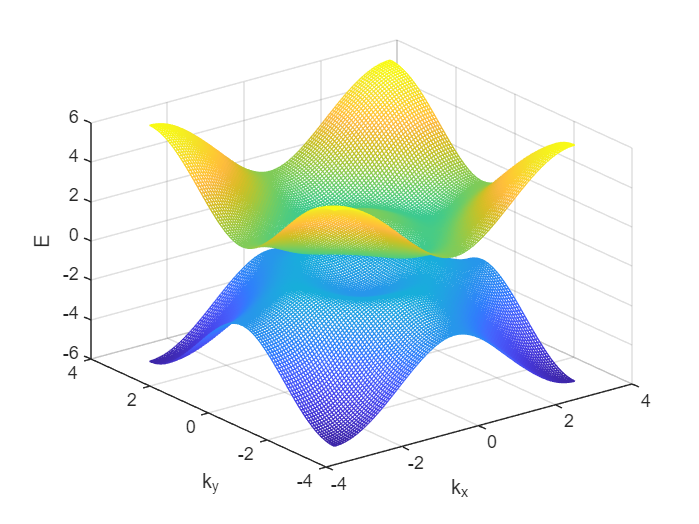


clear ;clc;

%energy ------------------------------------- 
kx_step = 101;
kx = [-pi,pi];
kx_list = linspace(kx(1), kx(2),kx_step);

ky_step = 101;
ky = [-pi,pi];
ky_list = linspace(ky(1), ky(2),ky_step);

Energy_band = zeros(kx_step, ky_step, 2);
a = 1; A = 1; B = 1; M = 2*B; %a:lattice length ; 

H = @(kx, ky) [M - 4*B*sin(kx*a/2)*sin(kx*a/2)-4*B*sin(ky*a/2)*sin(ky*a/2),A*sin(kx*a)-sqrt(-1)*A*sin(ky*a);
            A*sin(kx*a)+sqrt(-1)*A*sin(ky*a),-(M-4*B*sin(kx*a/2)*sin(kx*a/2)-4*B*sin(ky*a/2)*sin(ky*a/2))];
for ii = 1:kx_step
    for jj = 1:ky_step
        Energy_band(ii,jj,:) = eig(H(kx_list(ii), ky_list(jj)));
    end
end
[KX, KY] = meshgrid(kx_list, ky_list);
figure
mesh(KX, KY, Energy_band(:, :, 1));
hold on 
mesh(KX, KY, Energy_band(:, :, 2));
hold off
xlabel('k_x')
ylabel('k_y')
zlabel('E')

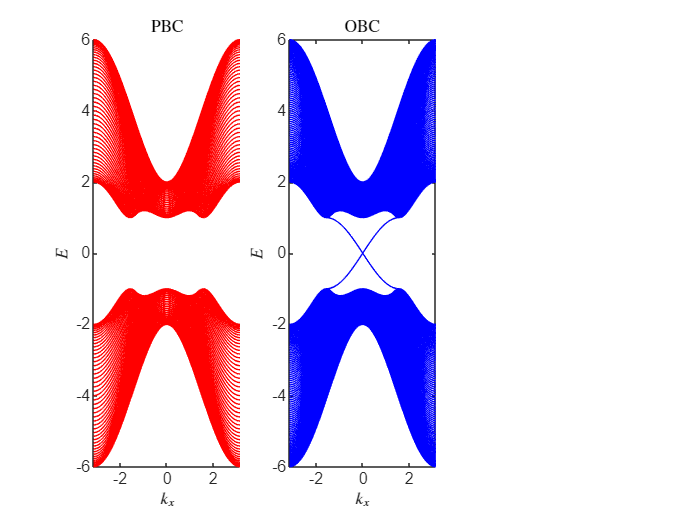

E1=reshape(Energy_band(:,:,1),[kx_step,ky_step]);
E2=reshape(Energy_band(:,:,2),[kx_step,ky_step]);
figure

%Dos_Ene(X,Y,E1,E2,num,b);
subplot(1,3,1);hold on;xlabel('$k_x$','Interpreter','latex');ylabel('$E$','Interpreter','latex');
title('PBC','Interpreter','latex');
plot(kx_list, E1, '-r'); plot(kx_list, E2, '-r');
hold off;


%edge state-------------------------------------------------
%x:PBC;y:OBC
h = zeros(2*ky_step,2*ky_step);
ene = zeros(kx_step,2*ky_step);
for ii=1:kx_step
    
    for jj=1:ky_step
        h(2*jj-1,2*jj-1)=M-2*B-4*B*sin(kx_list(ii)*a/2)*sin(kx_list(ii)*a/2);
        h(2*jj-1,2*jj)=A*sin(kx_list(ii)*a);
        h(2*jj,2*jj-1)=A*sin(kx_list(ii)*a);
        h(2*jj,2*jj)=-(M-2*B-4*B*sin(kx_list(ii)*a/2)*sin(kx_list(ii)*a/2));
    end
    for jj=1:ky_step-1
        h(2*jj-1,2*jj+1)=B;
        h(2*jj-1,2*jj+2)=-0.5*A;
        h(2*jj,2*jj+1)=0.5*A;
        h(2*jj,2*jj+2)=-B;
        
        h(2*jj+1,2*jj-1)=conj(h(2*jj-1,2*jj+1));
        h(2*jj+2,2*jj-1)=conj(h(2*jj-1,2*jj+2));
        h(2*jj+1,2*jj)=conj(h(2*jj,2*jj+1));
        h(2*jj+2,2*jj)=conj(h(2*jj,2*jj+2));
    end
    
    ene(ii,:)=eig(h);  %ene(16,30)
end
Kx=linspace(-pi,pi,kx_step);
subplot(1,3,2);
plot(Kx,ene,'-b');xlabel('$k_x$','Interpreter','latex');ylabel('$E$','Interpreter','latex');title('OBC','Interpreter','latex');

%grid on;

% %wavefunction-------------------------------   
% %edge state     x:PBC;y:OBC
kx_step=30;  %nx:the number of k_x; ny:the number of lattice y-diraction
a=1;A=1;B=1;M=2*B;%a:lattice length ;
ii=16%n_x=16处为零能点，所以在此k_x下寻找边缘态波函数

ii = 16


kx=-pi+(ii-1)*2*pi/kx_step;
ky_step=100;
    for jj=1:ky_step
        h(2*jj-1,2*jj-1)=M-2*B-4*B*sin(kx*a/2)*sin(kx*a/2);
        h(2*jj-1,2*jj)=A*sin(kx*a);
        h(2*jj,2*jj-1)=A*sin(kx*a);
        h(2*jj,2*jj)=-(M-2*B-4*B*sin(kx*a/2)*sin(kx*a/2));
    end
    for jj=1:ky_step-1
        h(2*jj-1,2*jj+1)=B;
        h(2*jj-1,2*jj+2)=-0.5*A;
        h(2*jj,2*jj+1)=0.5*A;
        h(2*jj,2*jj+2)=-B;
        
        h(2*jj+1,2*jj-1)=conj(h(2*jj-1,2*jj+1));
        h(2*jj+2,2*jj-1)=conj(h(2*jj-1,2*jj+2));
        h(2*jj+1,2*jj)=conj(h(2*jj,2*jj+1));
        h(2*jj+2,2*jj)=conj(h(2*jj,2*jj+2));
    end
    [V,D]=eig(h);D=diag(D);
    
    %search D and find D==0,when n=100

    x=linspace(0,ky_step,length(V(:,1)));

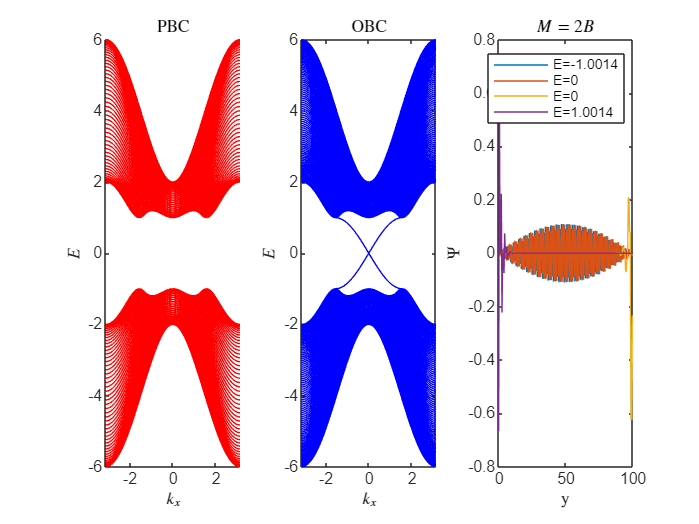

    subplot(1,3,3)
    plot(x,V(:,99),x,V(:,100),x,V(:,101),x,V(:,102));legend('E=-1.0014','E=0','E=0','E=1.0014')
    xlabel('y','Interpreter','latex'),ylabel('$\Psi$','Interpreter','latex');title('$M=2B$','Interpreter','latex');